Part 1 - Plot of refractive index vs wavelength

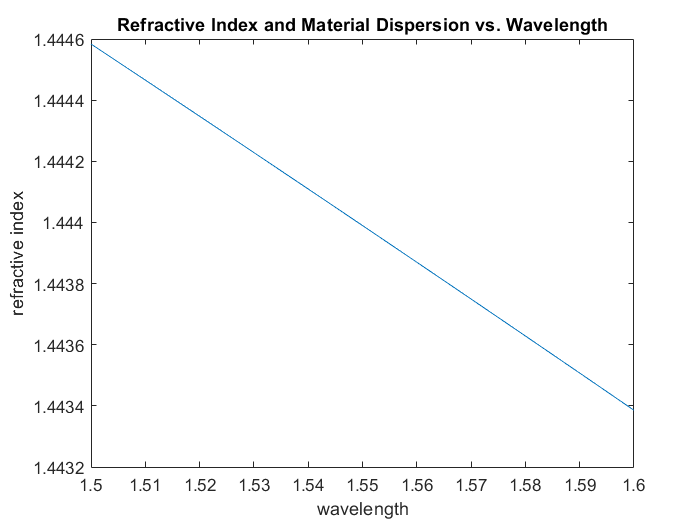

% declare the Sellmeier constants 
B1 = 0.696;
B2 = 0.408;
B3 = 0.897;

C1 = 4.679e-3;
C2 = 1.351e-2;
C3 = 97.934;

% use the linspace to get the range based off of the wavelength
% need to put the lambda values in micro meters for Sellmeier eqn.
lambda_o = linspace(1500e-3, 1600e-3, 1000);

% declare matrix for refractive index
n = zeros(size(lambda_o));

% use the sellmeier equation to get n
for i = 1:length(lambda_o)
    n(i) = sqrt(1 + (B1*lambda_o(i)^2)/(lambda_o(i)^2 - C1) + (B2*lambda_o(i)^2)/(lambda_o(i)^2 - C2) + (B3*lambda_o(i)^2)/(lambda_o(i)^2 - C3));
end

% plot the refractive index and material dispersion as a funct of wavelength below
plot(lambda_o, n)
xlabel('wavelength')
ylabel('refractive index')
xlim([1.5,1.6])
title('Refractive Index and Material Dispersion vs. Wavelength')

Part 2 - Plot of waveguide dispersion vs wavelength

% set constants 
delta = 0.003;
d = 2e-6;

lambda = linspace(1500e-9, 1600e-9, 1000);

% using the delta eqn from Q1 we get n2
n2 = n - delta.*n;

% get V using the eqn from Q2 
V = (2*pi*d.*n2*sqrt(2.*delta))./lambda;

% get b from given eqn
b = (0.5 - 0.1/V)^2;

Error using  / 
Matrix dimensions must agree.


% calculate the wave guide dispersion then the material disperion 
x_d = diff (b)./diff(V)




